# Składanie chmur punktów - elementy bazowe

## Przygotowanie zbioru danych

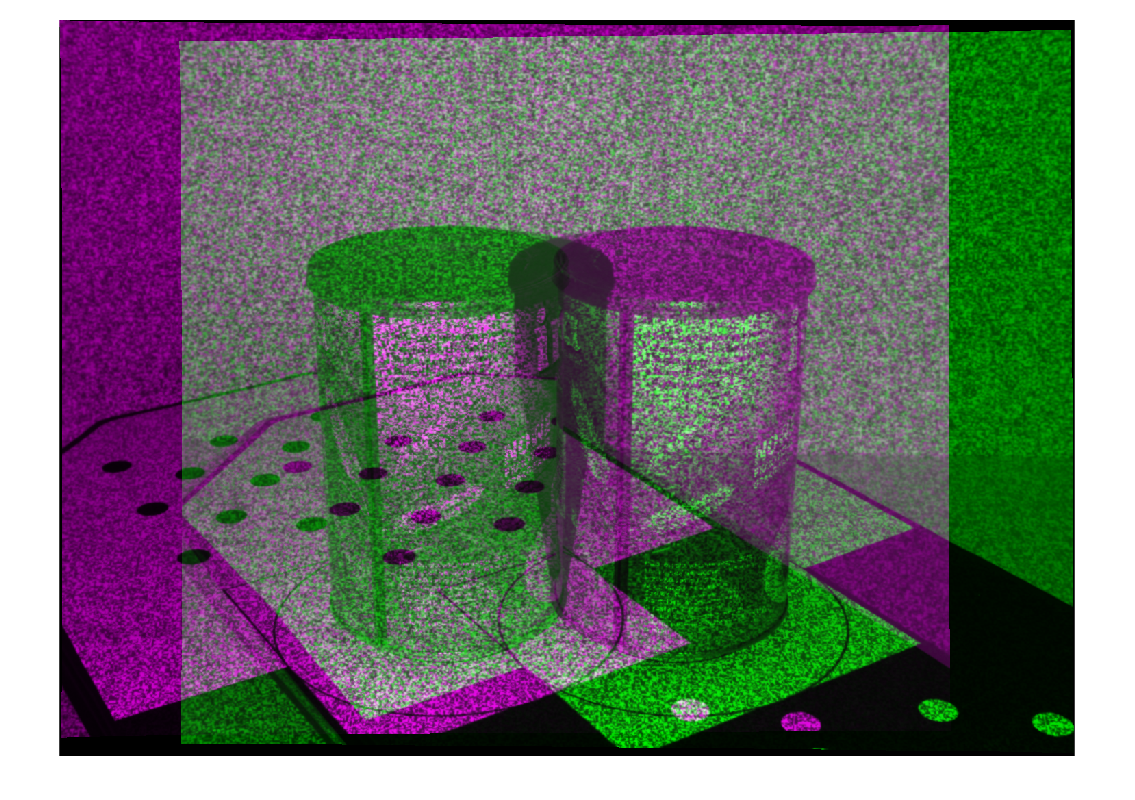

dif_left = imageDatastore('inka_dif/left');
dif_right = imageDatastore('inka_dif/right');

pat_left = imageDatastore('inka_pat/left');
pat_right = imageDatastore('inka_pat/right');

load stereoParams.mat

id = 3;

Ip1 = {};
Ip2 = {};
Id1 = {};
Id2 = {};

J1 = {};
J2 = {};
C1 = {};
C2 = {};

for k = 1:2

    Ip1{k} = readimage(pat_left, id + k - 1);
    Ip2{k} = readimage(pat_right, id + k - 1);
    Id1{k} = readimage(dif_left, id + k - 1);
    Id2{k} = readimage(dif_right, id + k - 1);
    
    [J1{k}, J2{k}, reprojectionMatrix] = rectifyStereoImages(Ip1{k}, Ip2{k}, stereoParams, 'OutputView','full');
    [C1{k}, C2{k}] = rectifyStereoImages(Id1{k}, Id2{k}, stereoParams, 'OutputView','full');

end

figure;
imshowpair(J1{1}, J2{1});

## Wyznaczenie disparity

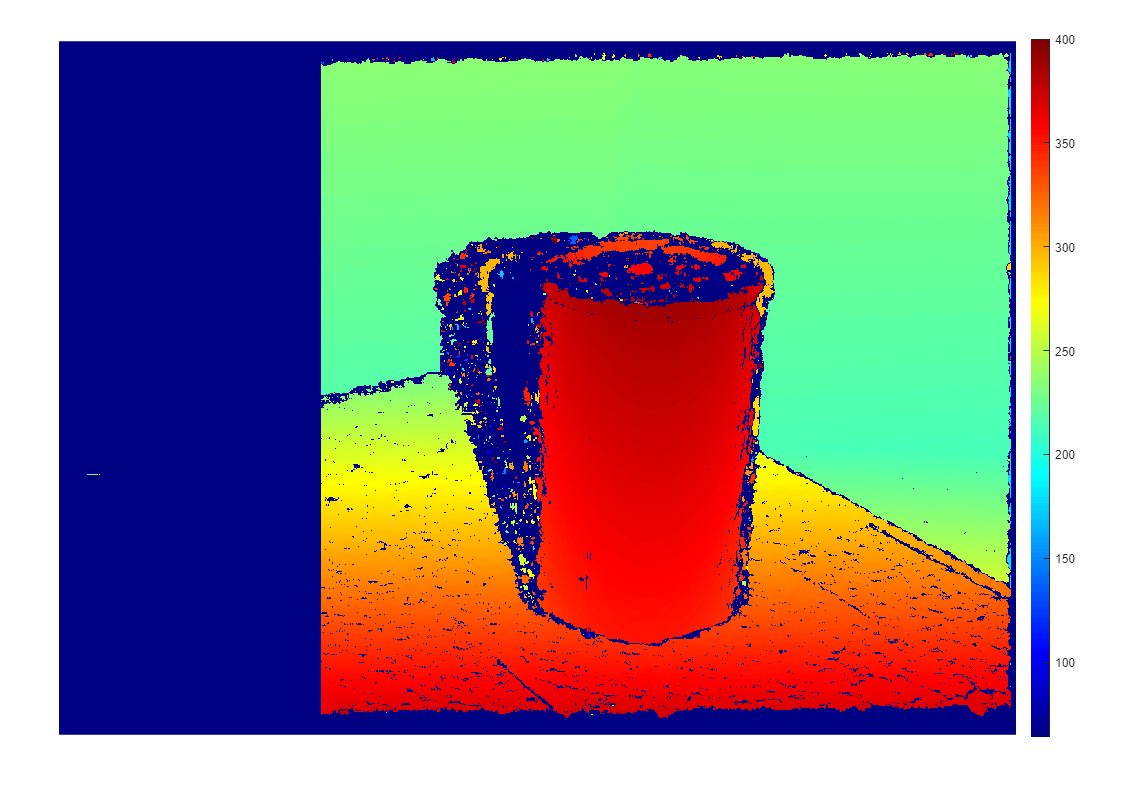

disparityRange = [64, 400];

dmap = {};

for k = 1:2
    dmap{k} = disparityBM(im2gray(J1{k}), im2gray(J2{k}), "DisparityRange", disparityRange, "BlockSize", 15, "UniquenessThreshold", 15, "TextureThreshold", 0.0002);
end

figure;
imshow(dmap{1}, disparityRange);
colormap('jet');
colorbar;

## Filtracja mapy disparity

Punkty bez wyznaczonego disparity oraz te znajdujące się dalej od kamery są zamieniane na wartości NaN

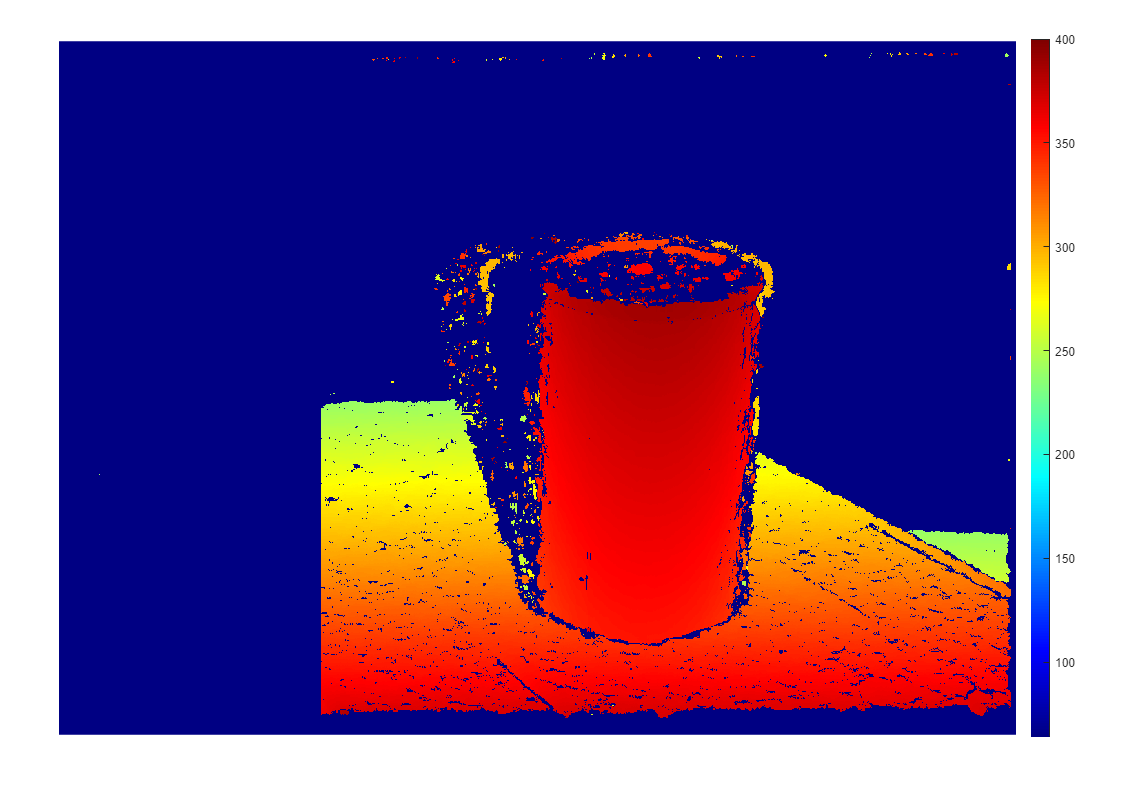

for k = 1:2
    dmap{k}(dmap{k} < 240) = NaN;
end

figure;
imshow(dmap{1}, disparityRange);
colormap(jet);
colorbar;

## Rekonstrukcja widoku 3D

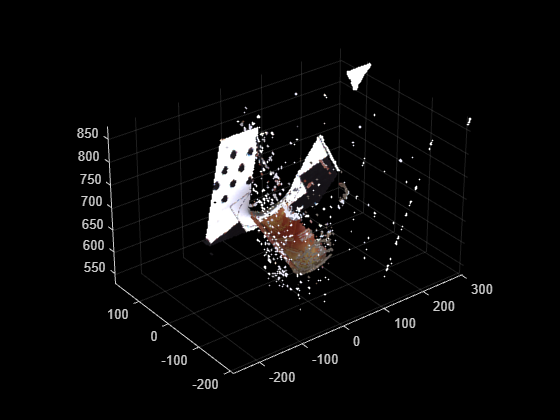

xyz = {};
cloud = {};

for k = 1:2
    xyz{k} = reconstructScene(dmap{k}, reprojectionMatrix);
    cloud{k} = pointCloud(xyz{k}, "Color", C1{k});
end

figure;
pcshow(cloud{1});

## Wyrównanie widoków

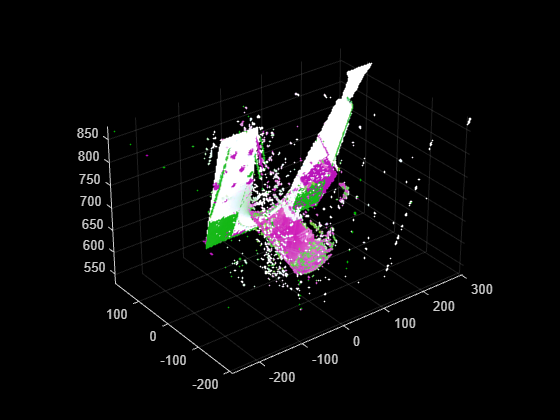

figure;
pcshowpair(cloud{1}, cloud{2});

### Detekcja punktów charakterystycznych w obrazach RGB

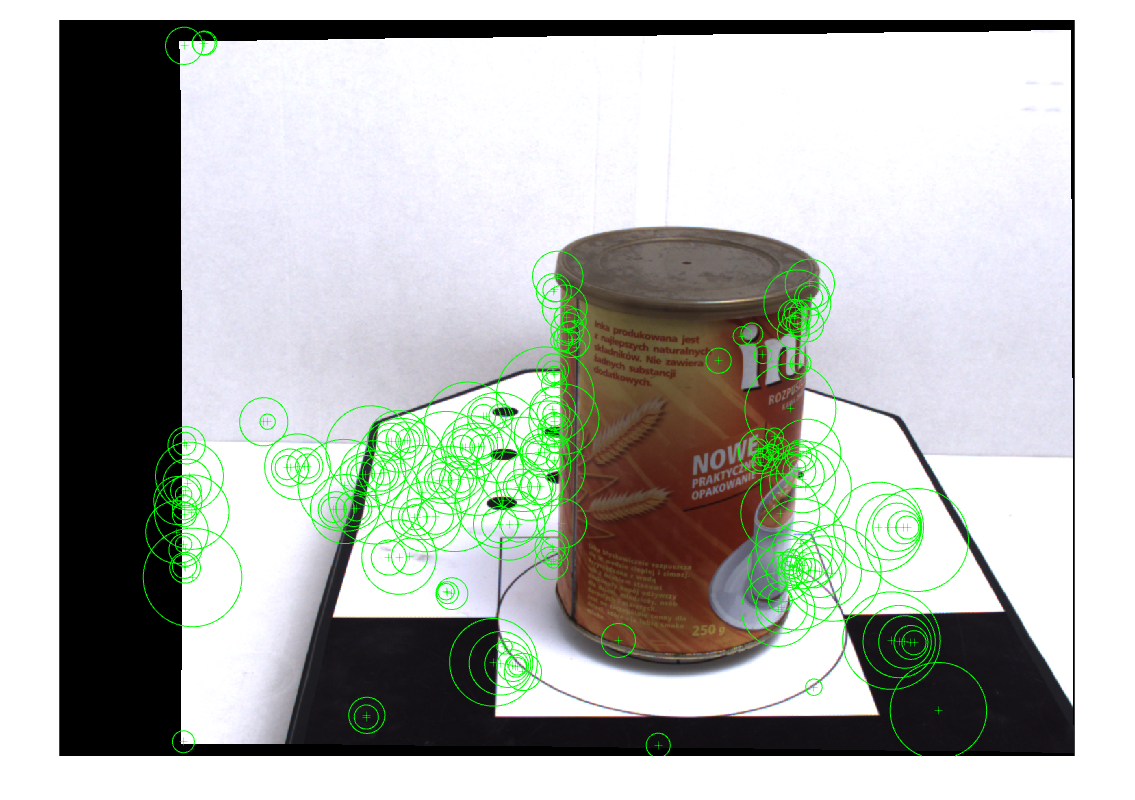

kpoints = {};
f = {};
vpts = {};

for k = 1:2
    kpoints{k} = detectSURFFeatures(im2gray(C1{k}), 'MetricThreshold', 100);
    [f{k}, vpts{k}] = extractFeatures(im2gray(C1{k}), kpoints{k});
end

figure;
imshow(C1{k});
hold on;
plot(kpoints{1}.selectStrongest(200));
hold off

### Odrzucenie punktów, które nie mają wyznaczonej disparity

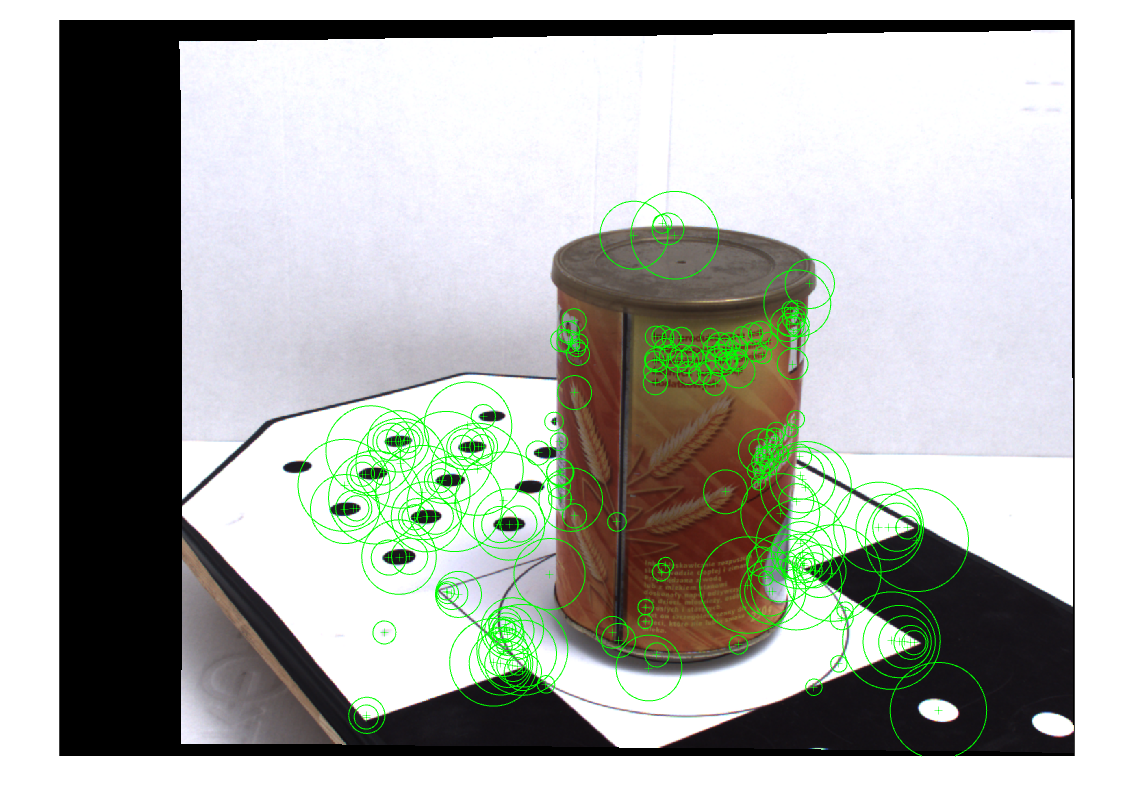

feats = {};
locs = {};
keypoints = {};

for k = 1:2
    
    keypointsMask = zeros(size(vpts{k}));
    tmpLocs = zeros(size(vpts{k}, 1), 3);

    for p = 1:length(vpts{k}.Location)
        x = round(vpts{k}.Location(p, 1));
        y = round(vpts{k}.Location(p, 2));
    
        if isfinite(dmap{k}(y, x))
            keypointsMask(p) = 1;
            tmpLocs(p, :) = xyz{k}(y, x, :);
        end
    end
    
    keypoints{k} = vpts{k}(keypointsMask == 1);
    locs{k} = tmpLocs(keypointsMask == 1, :);
    feats{k} = f{k}(keypointsMask == 1, :);

end

figure;
imshow(C1{1});
hold on;
plot(keypoints{1}.selectStrongest(200));
hold off

### Wyznaczenie dopasowań pomiędzy dwoma widokami

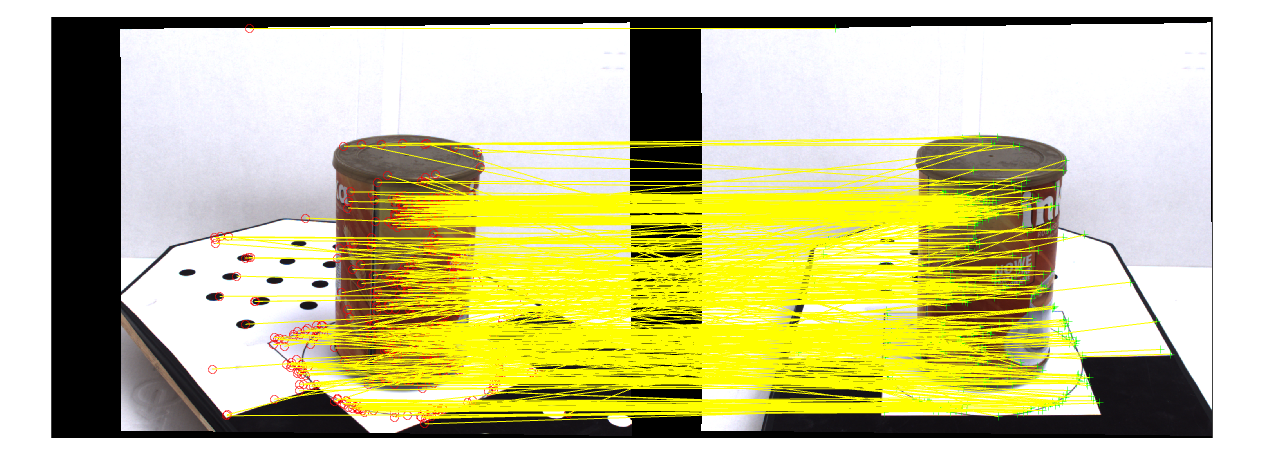

tforms = {};

% Przekształcenie pomiędzy układem kamery a powierzchnią stolika
tforms{1} = rigidtform3d([-113, 0.3, 0], [0, 0, 343]);

tclouds = {};
tclouds{1} = pctransform(cloud{1}, tforms{1});

matches = matchFeatures(feats{1}, feats{2}, 'MaxRatio', 1, "MatchThreshold", 5.0, "Unique", true);

locs1 = locs{1}(matches(:,1), :);
locs2 = locs{2}(matches(:,2), :);

figure;
showMatchedFeatures(C1{1}, C1{2}, keypoints{1}(matches(:,1), :), keypoints{2}(matches(:,2), :), "montage");

### Estymacja przekształcenia 3D

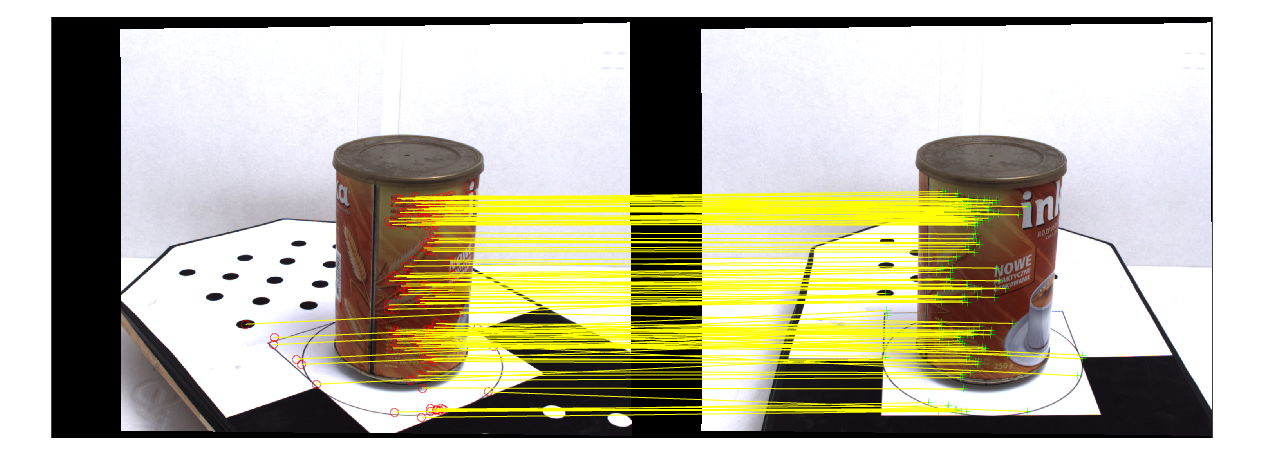

[tform, inliers] = estgeotform3d(locs2, locs1, "rigid", "MaxDistance", 6);

%tform2 = pcregistericp(clouds{id+1}, clouds{id}, "Metric", "pointToPoint", "InitialTransform", tform, "Verbose", false, "MaxIterations", 15, "InlierDistance", 3);

figure;
showMatchedFeatures(C1{1}, C1{2}, keypoints{1}(matches(inliers,1), :), keypoints{2}(matches(inliers,2), :), "montage");

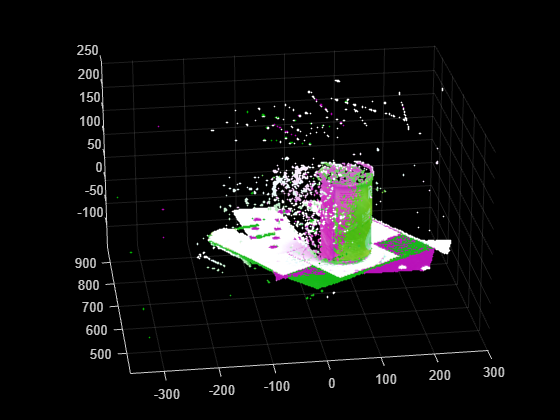

tforms{2} = tform;

tclouds{2} = pctransform(cloud{2}, tforms{2});
tclouds{2} = pctransform(tclouds{2}, tforms{1});

figure;
pcshowpair(tclouds{1}, tclouds{2});

## Połączenie chmur i wybór największego segmentu

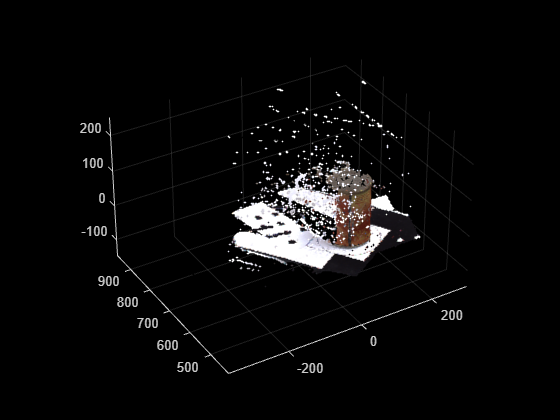

merged = pcmerge(tclouds{1}, tclouds{2}, 1);
pcshow(merged);

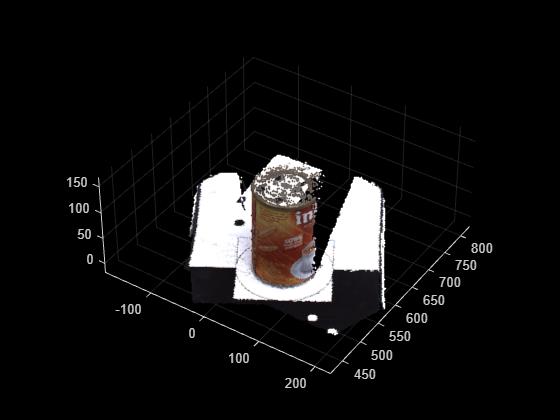

[labels, numClusters] = pcsegdist(merged, 8);
figure;
biggest = select(merged, find(labels == mode(labels)));
pcshow(biggest);